%plant kecepatan motor dc
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
motor = K/((J*s+b)*(L*s+R)+K^2);
zpk(motor)

ans =
 
           2
  -------------------
  (s+9.997) (s+2.003)
 
Continuous-time zero/pole/gain model.



%PID
kp=10;
ki=20;
kd=1;
pid= kp + ki/s +kd*s;
zpk(pid)

ans =
 
  (s+7.236) (s+2.764)
  -------------------
           s
 
Continuous-time zero/pole/gain model.



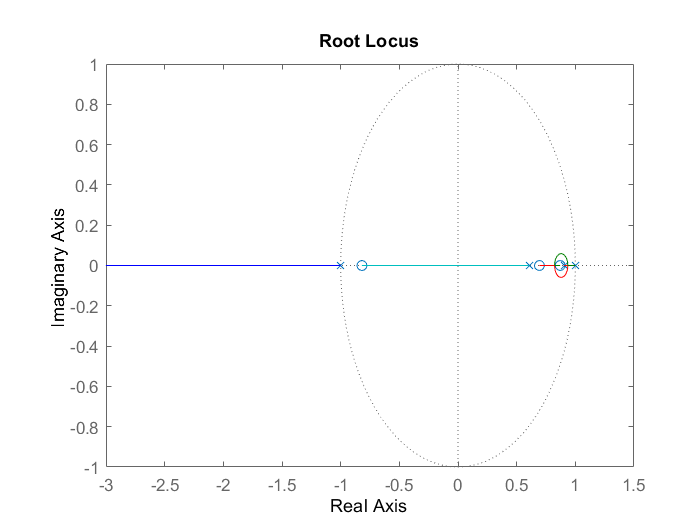

% A/D motor dc
Ts = 0.05;
d_motor = c2d(motor,Ts,'zoh');
zpk(d_motor);
dpid= c2d (pid,Ts,'tustin');
zpk(dpid);

z = tf('z',Ts);
rlocus(d_motor*dpid)

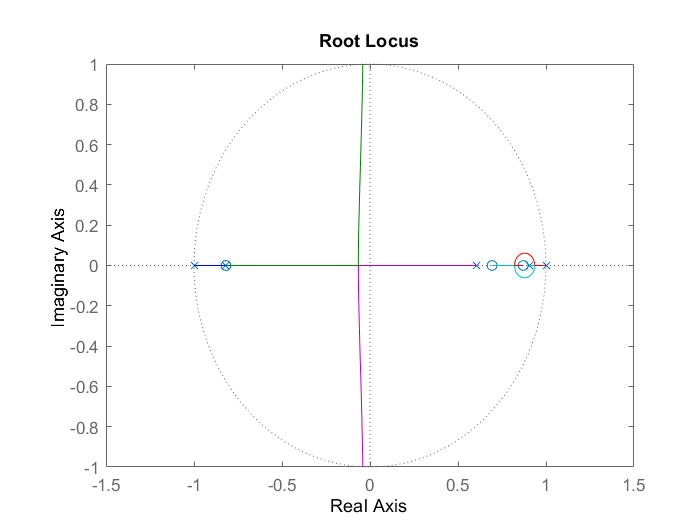

dpid = dpid/(z+0.8189);
rlocus(d_motor*dpid)

sys_cl=feedback(8.84*dpid*d_motor,1)

sys_cl =
 
             0.919 z^3 - 0.6851 z^2 - 0.6222 z + 0.4545
  -----------------------------------------------------------------
  z^5 - 0.6924 z^4 - 0.7698 z^3 + 0.4568 z^2 + 0.06658 z + 0.005093
 
Sample time: 0.05 seconds
Discrete-time transfer function.



zpk(sys_cl)

ans =
 
            0.91899 (z+0.8189) (z-0.8707) (z-0.6936)
  -------------------------------------------------------------
  (z+0.8189) (z^2 - 1.643z + 0.6749) (z^2 + 0.1317z + 0.009215)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.

